cd 'D:\Program Files\Polyspace\R2021a\bin\win64\0'
tic;close all;clear all
% 读取数据
D = [-2.28	-3.73	-3.63	-3.73	-0.65	-3.52	-3.21	-3.71	-3.72	-3.67	-3.64	-3.61	-3.65	-3.55	-3.54	-3.74	-3.75	-3.81	-3.71	-3.76	-3.64
    -8.37	-9.73	-9.73	-9.19	-9.68	-9.58	-2  	-9.9	-9.49	-9.93	-9.24	-9.95	-9.95	-9.46	-9.32	-9.55	-10.06	-9.51	-9.48	-9.77	-9.98
    -13.50	-12.18	-13.5	-11.18	-11.36	-12.33	-12.04	-12.41	-13.79	-12.98	-12.98	-13.53	-13.4	-12.32	-11.83	-12.39	-11.69	-11.86	-12.48	-13.08	-12.4
    -4.45	-5.25	-5.47	-5.05	-5.04	-5.48	-5.84	-5.25	-5.27	-5.04	-5.48	-5.14	-5.22	-5.59	-5.39	-5.12	-5.19	-5.1	-5.25	-5.19	-5.27
    0.536	0.538	0.537	0.538	0.537	0.537	0.526	0.515	0.522	0.544	0.529	0.535	0.546	0.527	0.533	0.531	0.522	0.535	0.536	0.529	0.532]';
y1 = D(:,1); % MD
y2 = D(:,2); % NADH
y3 = D(:,3); % FAD
y4 = D(:,4); % CT
y5 = D(:,end); % 溶解度评分
% [num, txt] = xlsread('E:\综合评价.xlsx','Main','A41:A61');
% clear num; save('txt','txt')
load txt
proteinlabel = txt';
xtick = 1:21;
% what is the pdb's name ?
if 1==1
    proteinlabel{1} = '5NA1';
    proteinlabel{19} = 'Wild';
end
% x = 1:21;
xs = [1 21];
toc

历时 0.564696 秒。


## FAD

tic
% 输入区
ob = "fad"

ob = "fad"

% draw(ob)
% lab01_draw

## Simple

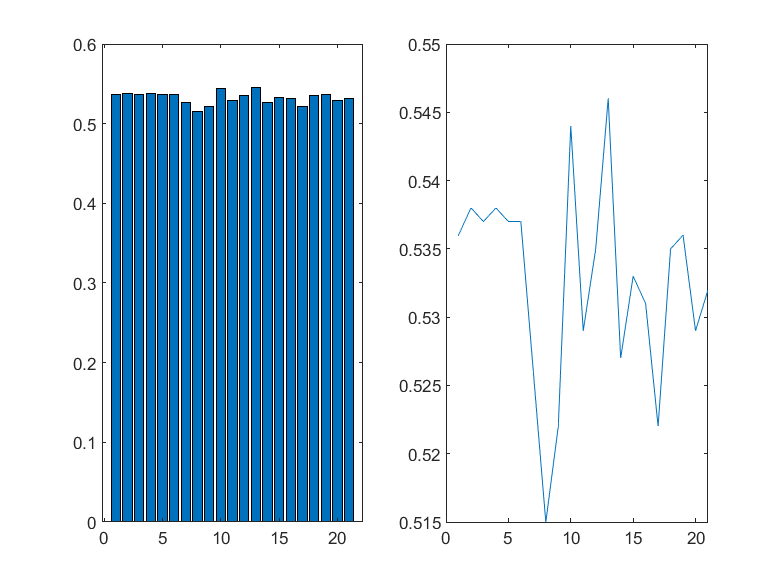

% 根本看不明白
figure
subplot(1,2,1); bar(D(:,5)); subplot(1,2,2); plot([1:21],D(:,5)')

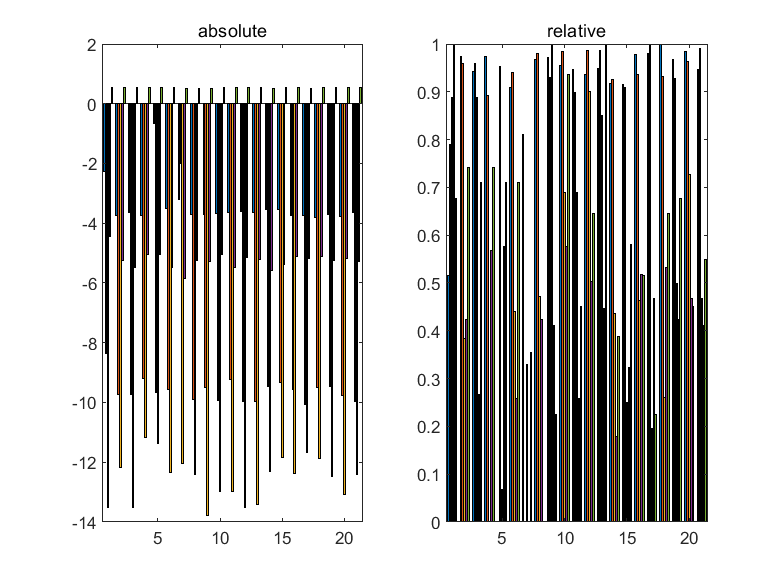

D1 = [-D(:,[1:3]) D(:,[4,5])]; % 同向化
for lgg=1:5; D2(:,lgg) = mapminmax(D1(:,lgg)',.0,1)'; end % 计算相对值
figure;subplot(1,2,1);bar(D);title('absolute');
subplot(1,2,2);bar(D2);title('relative'); hold off

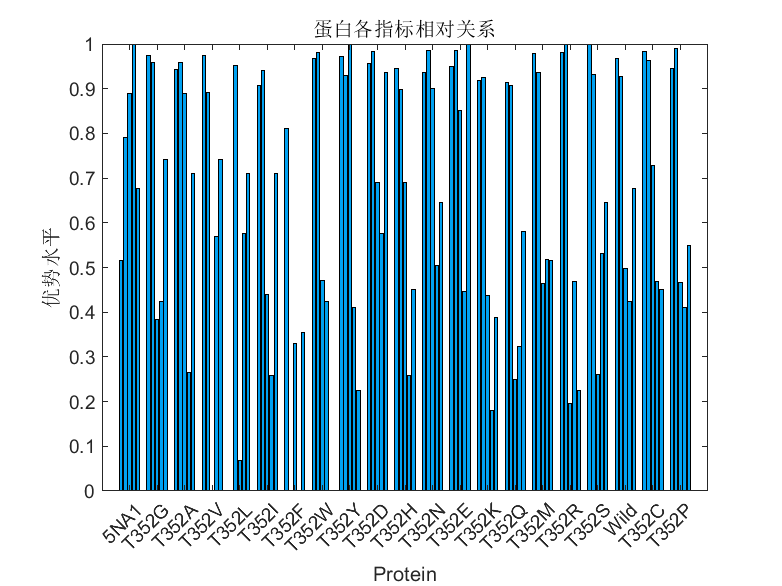

figure; b = bar(D2,'facecolor',color(3)); ylabel('优势水平'); % index relative value');
xlabel('Protein');
set(gca,'XLim',[0 22]);
set(gca,'XTick',xtick);
set(gca,'XTickLabel',proteinlabel);
title('蛋白各指标相对关系')

## Calculate

% close all
n = size(D,1) ; % 样本数量
m = zeros(n,1) ;
if1 = [y1,m,m m];
if2 = [m,y2,m m];
if3 = [m m y3 m];
if4 = [m m m y4];

## Graph 3 dots

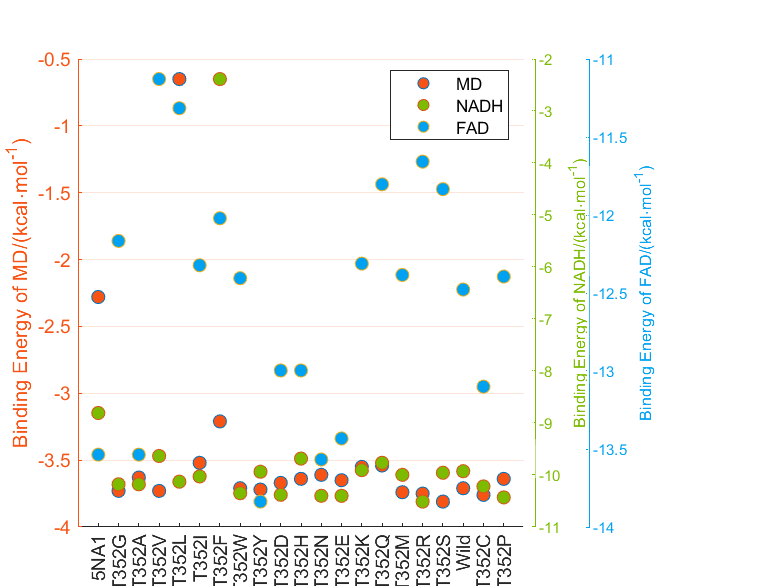

% clear;clc;close all;
% 获取到颜色
% [all_themes, all_colors] = GetColors();
all_colors = [246 83 20; 124 187 0; 0 161 241]/255;
sz = 50;
% figure;
x = 1:21;
% yyaxis left
% scatter(x, y1, 'filled');
% yyaxis right
% scatter(x, y2, 'filled');
% 三条线绘制到一起，注意数据都标准化到 y1 范围
maxY1 = max(y1); maxY2 = max(y2); maxY3 = max(y3);
minY1 = min(y1); minY2 = min(y2); minY3 = min(y3);
newY2 = (y2 - minY2)/(maxY2 - minY2);   % 归一化
newY2 = newY2*(maxY1 - minY1) + minY1;  % 反归一化
newY3 = (y3 - minY3)/(maxY3 - minY3);
newY3 = newY3*(maxY1 - minY1) + minY1;
w = 0.005; he = 0.8;
h.a = [0.1 0.1 0.57 he];
h.b = [0.68 0.1 w he];
h.c = [0.75 0.1 w he];

figure;
% title('（突变）蛋白的各项指标预测结果')
h1 = axes('position', h.a);
xlabel('Protein');
set(gca,'XLim',[0 22]);
set(gca,'XTick',xtick);
set(gca,'XTickLabel',proteinlabel);
ylabel('Binding Energy of MD/(kcal\cdotmol^{-1})');
set(gca,'ygrid','on')
% 显示数据
hold on
scatter(x, y1, sz, 'MarkerFaceColor', all_colors(1, :));
scatter(x, newY2, sz, 'MarkerFaceColor', all_colors(2, :));
scatter(x, newY3, sz, 'MarkerFaceColor', all_colors(3, :));
legend('MD','NADH','FAD','Location','best');
hold off

h1.YColor = all_colors(1, :);
% 绘制另外两个空的坐标轴
h2 = axes('position', h.b);
% 重复绘制，曲线颜色用白色，和figure背景色一致，看不出来即可
plot(x, y2, 'w')
% 颜色，位置，曲线标签
set(h2, 'ycolor', all_colors(2, :), 'yaxislocation', 'right', 'xtick', [])
% 边界显示不清楚，所以画一条线
hold on
limX2 = get(h2, 'Xlim');
limY2 = get(h2, 'Ylim');
plot([limX2(2),limX2(2)], limY2, 'Color', all_colors(2, :));
% BUG:出于未知原因，以上x轴数据不可省略，否则导致部分y轴被空白覆盖
hold off
% 取消边框
box off
ylabel('Binding Energy of NADH/(kcal\cdotmol^{-1})');
h3 = axes('position', h.c);
plot(x, y3, 'w')
set(h3, 'ycolor', all_colors(3, :), 'yaxislocation', 'right', 'xtick', [])
hold on
limX3 = get(h3, 'Xlim');
limY3 = get(h3, 'Ylim');
plot([limX3(2), limX3(2)], limY3, 'Color', all_colors(3, :));
hold off
box off
ylabel('Binding Energy of FAD/(kcal\cdotmol^{-1})');


% 取消坐标轴的颜色，和figure统一
% set(h1, 'color','none')
% set(h2, 'color','none')
% set(h3, 'color','none')
% figure背景设置成白色
set(gcf,'color','white');


## Graph Comprehansive Evaluate

tic
cd 'D:\Program Files\Polyspace\R2021a\bin\win64\0\evaluate'
run lab01_evaluate;

rs = 21×8 string 数组
    "T352_"    "0.773"      "4"     "0.072788"    "1"     "0.44919"      "4"     "3"      
    "T352G"    "0.6846"     "9"     "0.047201"    "10"    "0.19496"      "7"     "8.6667" 
    "T352A"    "0.77067"    "5"     "0.058527"    "5"     "0.31587"      "5"     "5"      
    "T352V"    "0.60151"    "15"    "0.038276"    "15"    "0.02639"      "13"    "14.3333"
    "T352L"    "0.43352"    "20"    "0.034529"    "19"    "-0.89562"     "20"    "19.6667"
    "T352I"    "0.64802"    "14"    "0.043812"    "14"    "-0.04401"     "14"    "14"     
    "T352F"    "0.31349"    "21"    "0.021789"    "21"    "-1.5648"      "21"    "21"     
    "T352W"    "0.55599"    "18"    "0.036544"    "17"    "-0.36196"     "18"    "17.6667"
    "T352Y"    "0.72274"    "6"     "0.056834"    "6"     "0.1308"       "11"    "7.6667" 
    "T352D"    "0.82677"    "2"     "0.064245"    "3"     "0.71815"      "2"     "2.3333" 
    "T352H"    "0.65634"    "12"    "0.047016"    "11"    "-0.091002" 

% close all
nn = 6;
ob = score(:,[1:2:nn]);
% 功效系数法将评分映射到[60 100]
score(:,[1:2:nn]) = 60+40*(ob-min(ob))./(max(ob)-min(ob));
y1 = score(:,[1:2:nn]);
y2 = score(:,[2:2:nn]);
% n = size(y1,1) ; % 样本数量
% h = nn/2; % 列数 column
% m = zeros(n,h) ;
if1 = [y1];
if2 = [y2];
S = score(:,end);
[SD,I] = sort(S);
for i=1:21
    ID = I(i);
    If1(i,:) = if1(ID,:);
    If2(i,:) = if2(ID,:);
    XL(i,:) = proteinlabel(ID);
end

% 三评分折线数据
abscissas.d = 0.25;
abscissas.raw = 1:21;
for i = 1:3
    abscissas.value(i,:) = abscissas.raw + abscissas.d *(i-2);
end


figure()
cd 'D:\Program Files\Polyspace\R2021a\bin\win64\0'
left_color = color(5);
right_color = color(6);
set(figure,'defaultAxesColorOrder',[left_color; right_color]);
yl1 = '各评价方法评分';% Each Evaluation Method Scores
yl2 = '各评价方法排名';% Each Evaluation Method Ranking
yyaxis left
ylabel(yl1)
hold on
b1 = bar(If1,'FaceColor',left_color);

yyaxis right
ylabel(yl2)
% b2 = bar(If2,'FaceColor',right_color);
% 折线&散点图
hold on
for i=1:3;
    plot(abscissas.value(i,:),If2(:,i),'LineWidth',2.5);
    sca = scatter(abscissas.value(i,:),If2(:,i),50,'filled','s');
end
% clear sca
% sca = scatter(abscissas.value(i,:),If2(:,i),50,'filled','s');


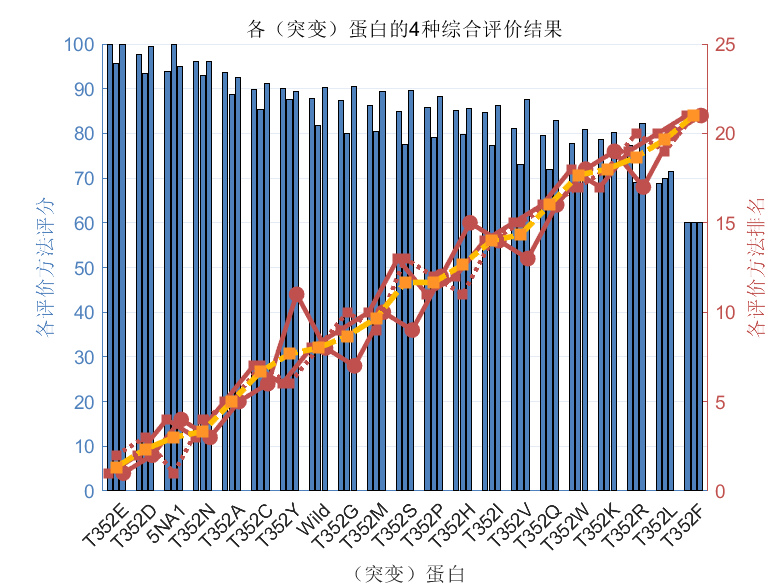

% 综合评分折线&散点
p3 = plot([1:21],SD,"Color",color(4),'LineWidth',3,'LineStyle',"-.");
scatter([1:21],SD,80,[255-00 187-40 0+40]/255,'filled','s')
% 解释性标注
% 设置横坐标刻度线数值
% 横坐标刻度
xtick = [1:21]; set(gca,'XTick',xtick); set(gca,'XTickLabel',XL);
xlabel('（突变）蛋白');% (Mutant) Proteins
% legend([b1(1),b2(1),p3],'各法得分','各法排名','平均位次','Location','northeast');
title('各（突变）蛋白的4种综合评价结果')% Comprehansive Evaluation of Each (Mutant) Proteins
set(gca,'ygrid','on')
hold off

toc

历时 3.369477 秒。


## more


% subplot(1,2,2)
% bar([1],y2(1,1)), hold on
% bar([2],y2(1,2)), hold on
% bar([3],y2(1,3)), grid on
% set(gca,'XTick',1:3,'XTickLabel',{'权威','权威','权威'})
% legend('A','B','C');
% set(gca,'FontSize',18)
% suptitle('权位职责统计')


## 分别作图（2×2）绝对点图

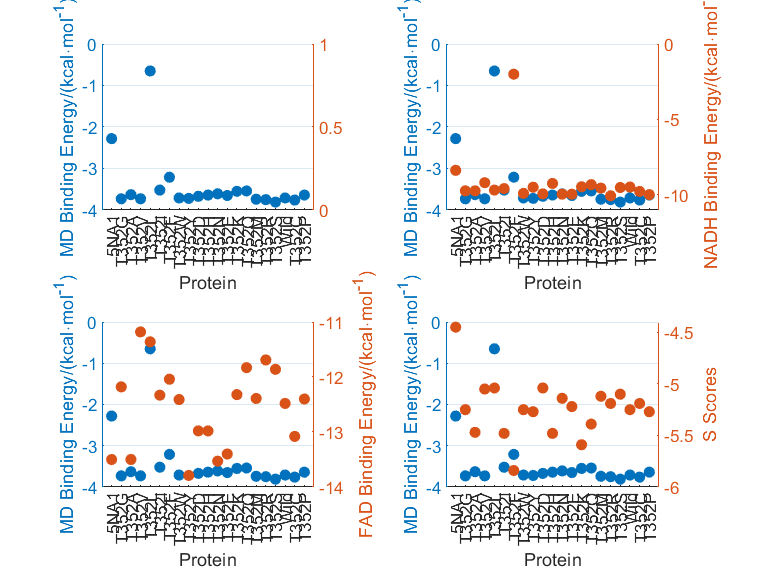

tic
% clear h
w = 0.005; he = 0.8;
h = [ 0.1 0.1 0.8 he
    0.68 0.1 w he
    0.75 0.1 w he ];

x = 1:21;
figure;
title('（突变）蛋白的各项指标预测结果')
hold on
ind = ["MD","NADH","FAD","S"]';
for lgg = 1:4
    %     if mod(i,2)==1
    %         j = 1
    %     else j = 2;
    %     end
    subplot(2,2,lgg)
    yyaxis left
    scatter(x, D(:,1), 'filled');
    ylabel(ind(1)+' Binding Energy/(kcal\cdotmol^{-1})');
    yyaxis right
    if lgg~=1
        scatter(x, D(:,lgg), 'filled');
        ylabel(ind(lgg)+' Binding Energy/(kcal\cdotmol^{-1})');
        if ind(lgg) == 'S'
            ylabel(ind(lgg)+' Scores');
        end
    else
        % bar([1,1],'FaceColor',[1 1 1])
        % ylabel('test','color','w')
    end
    xlabel('Protein');
    set(gca,'XLim',[0 22]);
    set(gca,'XTick',xtick);
    set(gca,'XTickLabel',proteinlabel);
    set(gca,'ygrid','on')
end
% 显示数据
hold off

toc

历时 0.592611 秒。
